# Práctica 3 - Parte 1 - Cuantización vectorial

Generar 1,000,000 de parejas de números (x,y) con una función de densidad uniforme de cada componente entre 0 y 100.

nSize = 1000000;
points = rand([nSize 2])*100;

Encontrar un cuantizador vectorial usando el algoritmo de Linde-Buzo-Gray para 8, 16, 64 y 256  regiones. Gráfique con colores la posición de los puntos en las diferentes regiones del cuantizador. Utilice para modificar los centroides una e1 = {0.0,0.001} y una e2 = {0.0,-0.001} y posteriormente nas e1 y e2 aleatorias. Compare los resultados entre usar unas e's fijas y unas aleatorias.

**8 regiones con e's fijas**

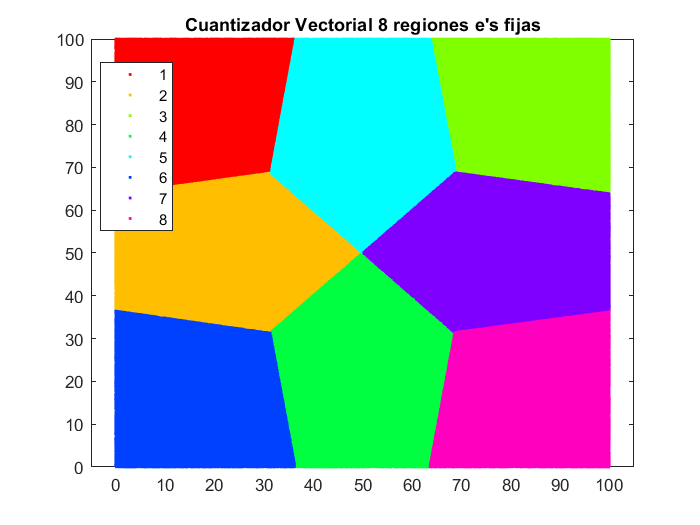

% Inicializa el número de clusters y el primer centroide
nClusters = 8;
C1 = 1/nSize *sum(points);

% Obtiene los centroides mediante el algoritmo de Linde Buzo Gray
% y grafica los puntos que fueron agrupados
idxLBG = LindeBuzoGray(C1, nClusters, points, false);
gscatter(points(:,1),points(:,2),idxLBG)
title('Cuantizador Vectorial 8 regiones e''s fijas')

**8 regiones con e's aleatorias**

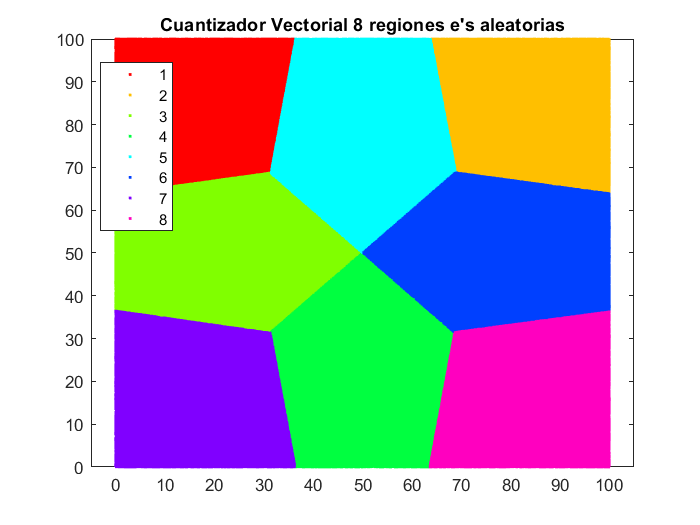

% Inicializa el número de clusters y el primer centroide
nClusters = 8;
C1 = 1/nSize *sum(points);

% Obtiene los centroides mediante el algoritmo de Linde Buzo Gray
% y grafica los puntos que fueron agrupados
idxLBG = LindeBuzoGray(C1, nClusters, points, true);
gscatter(points(:,1),points(:,2),idxLBG)
title('Cuantizador Vectorial 8 regiones e''s aleatorias')

**16 regiones con e's fijas**

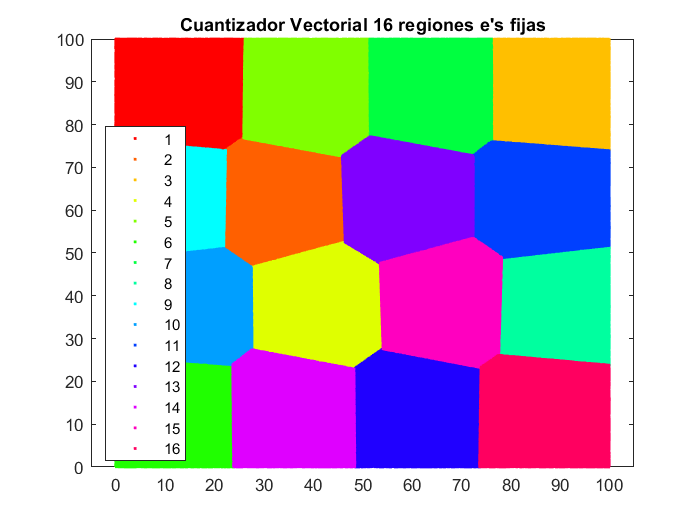

% Inicializa el número de clusters y el primer centroide
nClusters = 16;
C1 = 1/nSize *sum(points);

% Obtiene los centroides mediante el algoritmo de Linde Buzo Gray
% y grafica los puntos que fueron agrupados
idxLBG = LindeBuzoGray(C1, nClusters, points, false);
gscatter(points(:,1),points(:,2),idxLBG)
title('Cuantizador Vectorial 16 regiones e''s fijas')

**16 regiones con e's aleatorias**

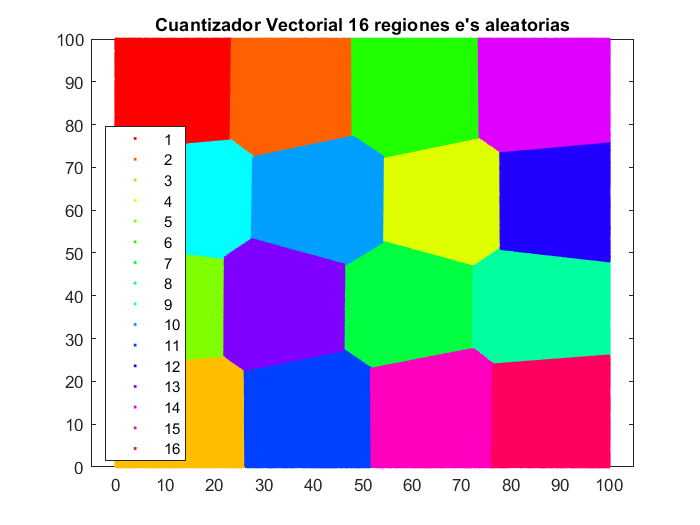

% Inicializa el número de clusters y el primer centroide
nClusters = 16;
C1 = 1/nSize *sum(points);

% Obtiene los centroides mediante el algoritmo de Linde Buzo Gray
% y grafica los puntos que fueron agrupados
idxLBG = LindeBuzoGray(C1, nClusters, points, true);
gscatter(points(:,1),points(:,2),idxLBG)
title('Cuantizador Vectorial 16 regiones e''s aleatorias')

Con los mismos puntos generados en el punto anterior encuentre las mismas regiones con el algorito de K-Medias, grafique éstas y compare con los obtenidos en el punto anterior. Comente sus resultados.

**8 regiones k-medias**

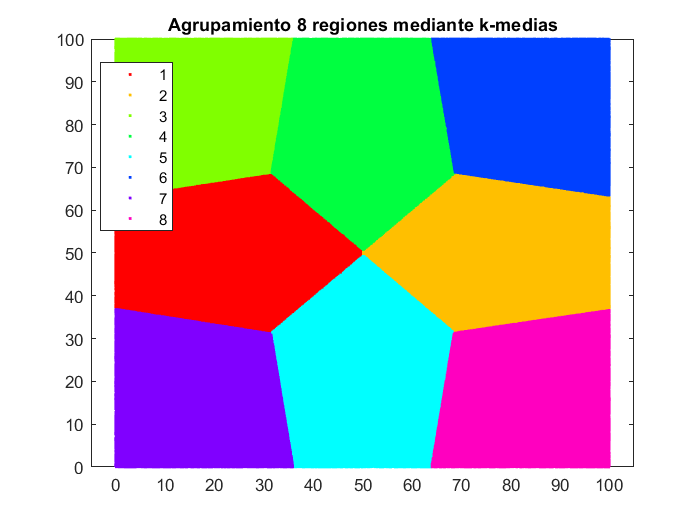

nClusters = 8;
idxMeans = kmeans(points, nClusters,'MaxIter',500);
gscatter(points(:,1),points(:,2),idxMeans);
title('Agrupamiento 8 regiones mediante k-medias')

**16 regiones k-medias**

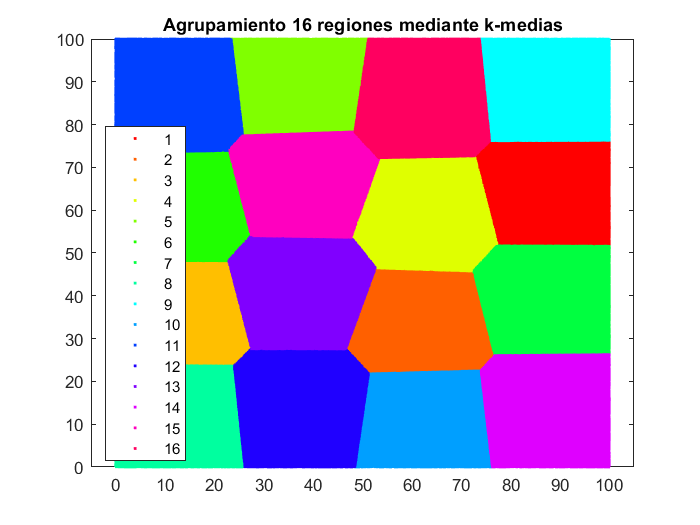

nClusters = 16;
idxMeans = kmeans(points, nClusters,'MaxIter',500);
gscatter(points(:,1),points(:,2),idxMeans);
title('Agrupamiento 16 regiones mediante k-medias')

**LindeBuzoGray**

Calcula los centroides del cuantizador vectorial para vectores en dos dimenciones utilizando el algoritmo de Linde - Buzo - Gray.

Parámetros:

- centroides: Vector con lista de centroides 

- nCuant: Número de centroides deseados, expresado en potencias de 2

- data: Conjunto de vectores para separar

- random: True implica usar epsilon aleatorio

Variables de retorno:

- indx: Vector de índices que indica a que grupo pertenece cada vector en data

- cuant: Centroides de los grupos generados

function  [indx,centroides] = LindeBuzoGray(centroides, nCuant, data, random)
    % Vectores epsilon para modificar los centroides
    e1 = [0.0,0.001]; e2 = [0.0,-0.001];
    if random == true
        e1 = [-rand(1), rand(1)]; e2 = [rand(1),-rand(1)];
    end
    % Matriz que contiene a los centroides modificados por los vectores
    % epsilon
    nCentroides = [centroides + e1; centroides + e2];
    % Estabiliza los centroides modificados
    [indx,centroides] = estabilizador(nCentroides, data);
    % Mientras la cantidad de centroides sea menor a la esperada
    % se mantiene generando más centroides y establizandolos
    if length(centroides) < nCuant
        [indx,centroides] = LindeBuzoGray(centroides, nCuant, data,random);
    end 
end

**Estabilizador**

Actualiza el valor del centroide basandose el valor promedio de los vectores cercanos a él, se detiene cuando la diferencia entre el centroide anterior y el nuevo sea menor a 2.0

Parámetros:

- centroides: Vector con lista de centroides 

- data: Conjunto de vectores para separar

Variables de retorno:

- indx: Vector de índices que indica a que grupo pertenece cada vector en data

- centroides: Centroides de los grupos generados

function [indx,centroides] = estabilizador(centroides, data)
    sizeCent = length(centroides);
    while true
        % Obtiene la matriz de distancias entre los datos y los centroides
        % Si n es el número de vectores que tiene datos y m el número de 
        % centroides se tiene una matriz de nxm
        distances = pdist2(data,centroides,'euclidean');
        % Obtiene la menor distancia de cada vector a algún centroide
        % así como el índice del centroide más cercano
        [distMenor,indx] = min(distances, [ ], 2);
        % Calcula la distancia global anterior
        distGAnterior = sum(distMenor);
        % Itera sobre los centroides
        for i = 1:sizeCent
            ind = indx==i;
            % Genera una submatriz que contenga a los vectores
            % más cercanos al iésimo centroide
            dataGroup = data(ind,:);
            % Recalcula el centroide tomando en cuenta el promedio de todos
            % los vectores que se agruparon en el mismo grupo
            centroides(i,:) = 1/length(dataGroup) * sum (dataGroup);
        end
        % Repite el proceso del cálculo de distancias para obtener
        % la distancia global actualizada
        distances = pdist2(data,centroides,'euclidean');
        [distMenor,indx] = min(distances, [ ], 2);
        distGActual = sum(distMenor);
        % Si la distancia global actual menos la distancia global
        % anterior es menor que un epsilon, los centroides han convergido
        if abs(distGActual - distGAnterior) < 0.5
            break
        end
    end
end